## Оценка параметров реального привода по данным из csv файла с нагрузкой

### Читаем CSV файл

clear; clc;
% test_csv = readmatrix("motor_data/ramp_0_100_1_with_load.csv");
% test_csv = readmatrix("motor_data/sin_664_with_load.csv");
test_csv = readmatrix("motor_data/sin_664_with_load_v2.csv");
% test_csv = readmatrix("motor_data/sin_664.csv");
% test_csv = readmatrix("motor_data/sin_664_v2.csv");

% test_csv(2,2)
% data_length = length(test_csv(:,2))-1
% time = test_csv(2:data_length+1, 2);    % мкс
% ticks = test_csv(2:data_length+1, 3) / 15000 * 2 * pi;  % рад
% input = test_csv(2:data_length+1, 4) / 100 * 12;    % В
% current = test_csv(2:data_length+1, 5) / 1000;  % А
% current_orig = current;

test_csv(2,2)

ans = 11794881

data_length = length(test_csv(:,2))-1

data_length = 9973

time = test_csv(2:data_length+1, 2);    % мкс
ticks = test_csv(2:data_length+1, 3);  % рад
input = test_csv(2:data_length+1, 4) / 100 * 12;    % В
current = test_csv(2:data_length+1, 5) / 1000;  % А
current_orig = current;

t_start = time(1);
time = (time - t_start)/1000000;    % с

dticks = zeros(1, data_length);
dticks_orig = zeros(1, data_length);
dticks_smooth = zeros(1, data_length);

ddticks = zeros(1, data_length);
ddticks_orig = zeros(1, data_length);

dI = zeros(1, data_length);
dI_orig = zeros(1, data_length);

f_w = 1

f_w = 1

f_b = 0.7

f_b = 0.7000

f_i = 1

f_i = 1

f_di = 0.05

f_di = 0.0500

dt = time(2)-time(1)

dt = 0.0016


ticks = smooth(ticks, 3);

for k = 2:data_length
    dt = time(k)-time(k-1);

    dticks_orig(k) = ( ticks(k)-ticks(k-1) )/dt;
    ddticks_orig(k) = ( dticks_orig(k)-dticks_orig(k-1) )/dt;
    dI_orig(k) = ( current(k)-current(k-1) )/dt;

    dticks(k) = dticks(k-1)*(1-f_w) + f_w * ( ticks(k)-ticks(k-1) )/dt;

%     ddticks(n) = ( dticks(n)-dticks(n-1) )/dt;
%     ddticks(n) = ddticks(n-1)*(1-f_b) + f_b * ( dticks(n)-dticks(n-1) )/dt;
    ddticks(k) = ddticks(k-1)*(1-f_b) + f_b * ( dticks_orig(k)-dticks_orig(k-1) )/dt;
    
    dI(k) = dI(k-1)*(1-f_di) + f_di * ( current(k)-current(k-1) )/dt;
end

dticks = smooth(dticks, 3);

% works for sin_664.csv
current = smooth(current, 3);
ddticks = smooth(ddticks, 5);
dI = smooth(dI, 5);

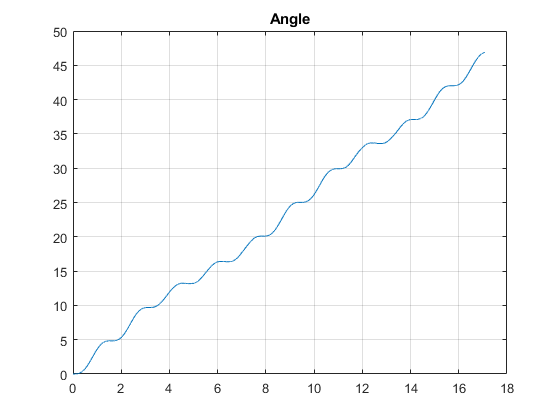

figure;
plot(time, ticks)
title("Angle")
xlim("auto")
ylim("auto")
grid on

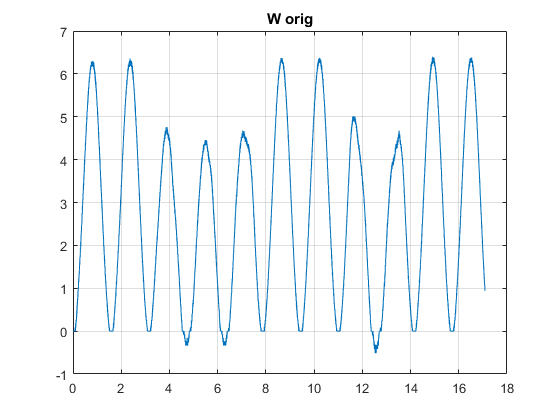


plot(time, dticks_orig)
title("W orig")
xlim("auto")
ylim("auto")
grid on

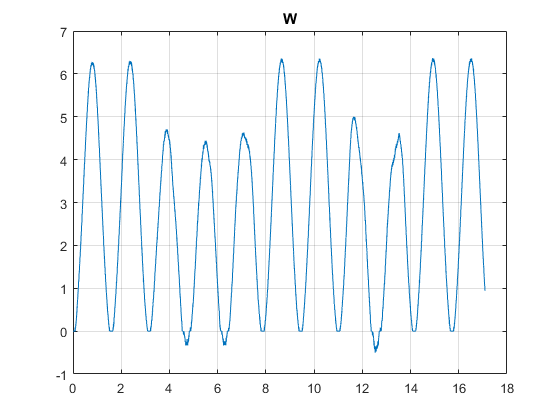


plot(time, dticks)
% hold
% plot(time, dticks_orig)
% hold 
title("W")
xlim("auto")
ylim("auto")
grid on

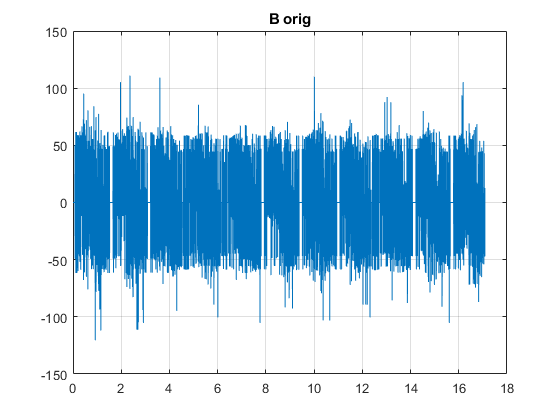


% plot(time_smooth, dticks_smooth)
% % plot(time, dticks_smooth)
% title("W smooth")
% xlim("auto")
% ylim("auto")
% grid on

plot(time, ddticks_orig)
title("B orig")
xlim("auto")
ylim("auto")
grid on

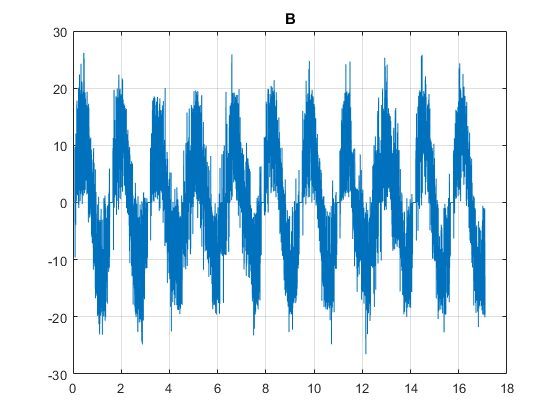


plot(time, ddticks)
title("B")
xlim("auto")
ylim("auto")
grid on

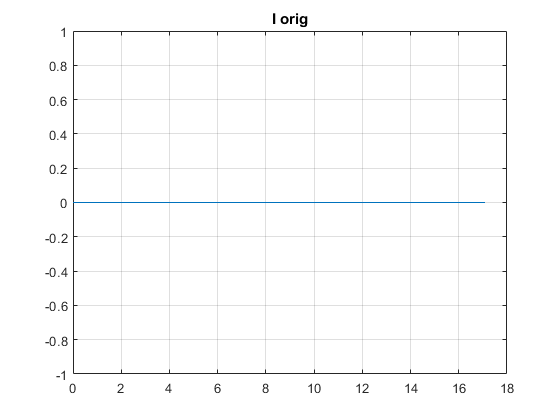


plot(time, current_orig)
title("I orig")
xlim("auto")
ylim("auto")
grid on

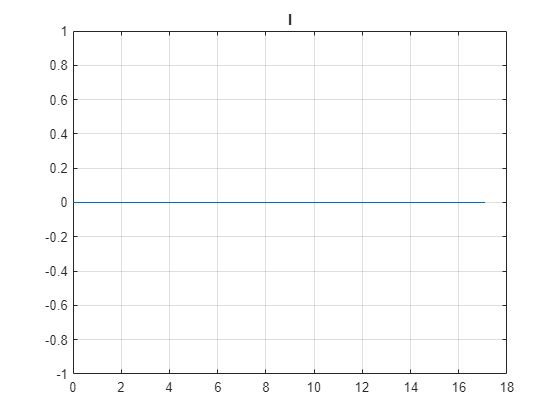


plot(time, current)
title("I")
xlim("auto")
ylim("auto")
grid on

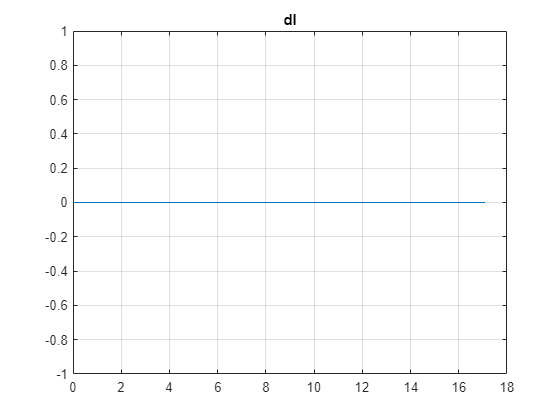


plot(time, dI_orig)
title("dI orig")
xlim("auto")
ylim("auto")
grid on

title("dI")

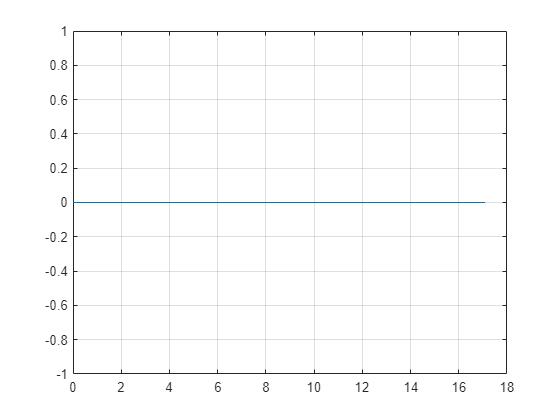

plot(time, dI)
xlim("auto")
ylim("auto")
grid on

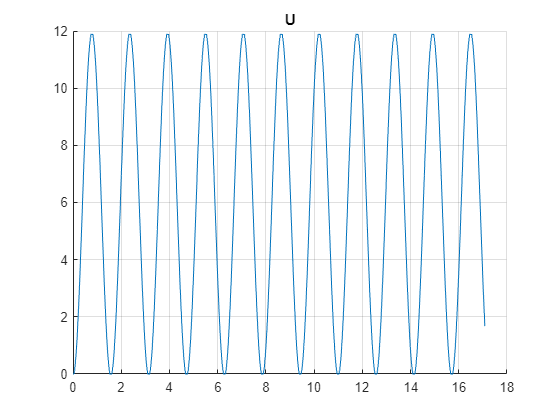


figure
title("U")
hold on
plot(time, input)
% plot(time, dticks)
hold off
xlim("auto")
ylim("auto")
grid on

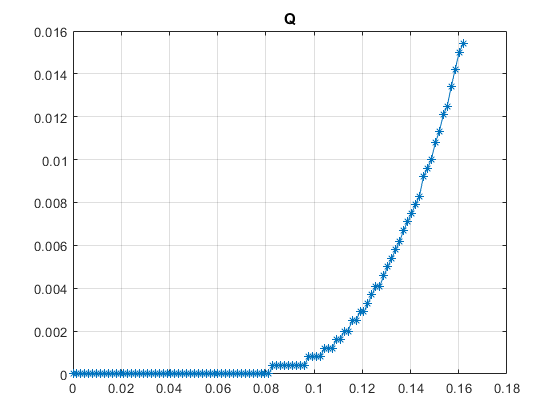

% start = 3500;
% finish = 3550;

start = 1;
finish = 100;

figure;
plot(time(start:finish), ticks(start:finish), '*-')
% plot(time(start:finish), ticks(start:finish))
title("Q")
xlim("auto")
ylim("auto")
grid on

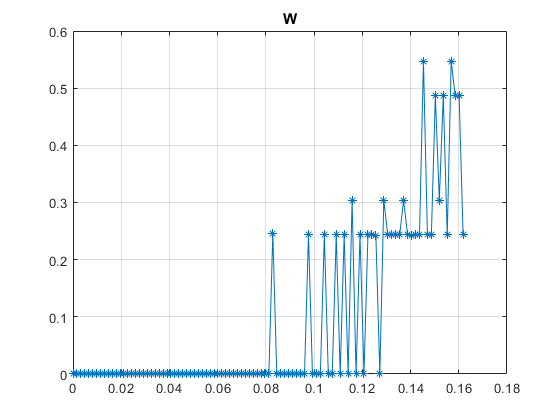


figure;
plot(time(start:finish), dticks(start:finish), '*-')
title("W")
xlim("auto")
ylim("auto")
grid on

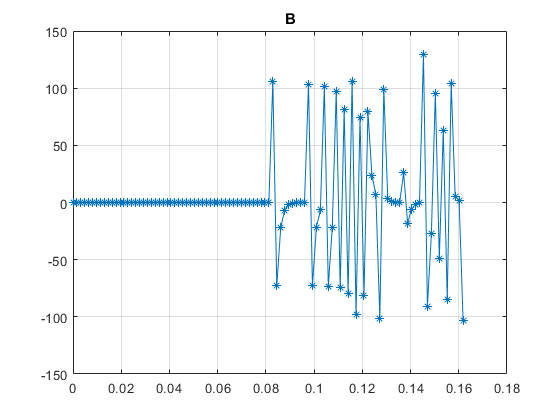


figure;
plot(time(start:finish), ddticks(start:finish), '*-')
title("B")
xlim("auto")
ylim("auto")
grid on

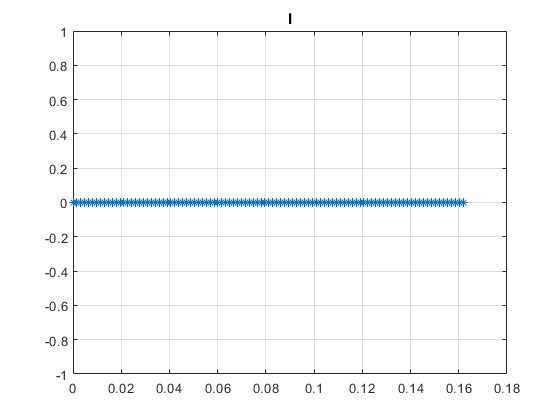


figure;
plot(time(start:finish), current(start:finish), '*-')
title("I")
xlim("auto")
ylim("auto")
grid on

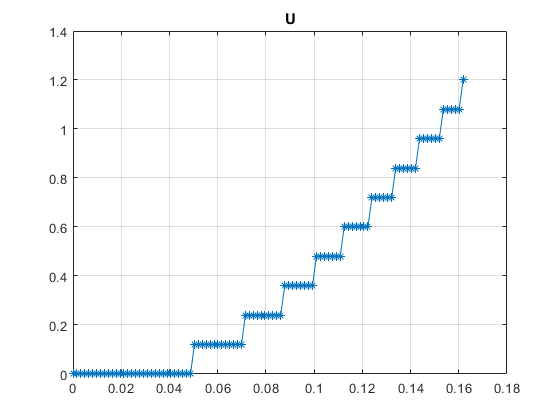


figure;
plot(time(start:finish), input(start:finish), '*-')
title("U")
xlim("auto")
ylim("auto")
grid on

### Parameters identification with kalman filter model with load and Kw Km

% from offline parameter identification with KF
L = 1.0551;
R = 5.9043;
Kw = 1.9437;
Km = 1.9437;
J = 0.0085;
Lam = 0.0020;

% random me
% L = 1;
% R = 30;
% Kw = 1;
% Km = 1;
% J = 1;
% Lam = 1e-3;

% random
% L = rand();
% R = 30; % Ом, я замерил
% Kw = rand();
% Km = rand();
% J = rand();
% Lam = rand();

% V3 + load
% x = [w dw I]'
% u = [Mext u]'
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L]

A = 1.0e+03 *

   -0.0002         0    0.2287
   -0.4213   -0.0002   -1.2796
   -0.0018         0   -0.0056


B = [1/J 0;
     0   Km/(J*L);
     0   1/L]

B =   117.6471         0
         0  216.7288
         0    0.9478


C = eye(3)

C =      1     0     0
     0     1     0
     0     0     1


D = [0 0 0]'

D =      0
     0
     0



C_lqe = [1 0 0;
         0 1 0;
         0 0 0];
[Te, De] = eig(A)

Te =    0.0000 + 0.0000i  -0.0069 - 0.0481i  -0.0069 + 0.0481i
   1.0000 + 0.0000i   0.9988 + 0.0000i   0.9988 + 0.0000i
   0.0000 + 0.0000i   0.0044 - 0.0000i   0.0044 + 0.0000i


De =   -0.2353 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.9156 +20.3488i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.9156 -20.3488i


Cc = ctrb(A,B)

Cc = 1.0e+05 *

    0.0012         0   -0.0003    0.0022   -0.4955   -0.0126
         0    0.0022   -0.4956   -0.0126    3.0066   -0.8421
         0    0.0000   -0.0022   -0.0001    0.0126   -0.0037


Cob = obsv(A, C_lqe)

Cob = 1.0e+04 *

    0.0001         0         0
         0    0.0001         0
         0         0         0
   -0.0000         0    0.0229
   -0.0421   -0.0000   -0.1280
         0         0         0
   -0.0421         0   -0.1333
    0.2556    0.0000   -8.8867
         0         0         0


rank(Cc)

ans = 3

rank(Cob)

ans = 3


Vd_w = 1e2;
Vd_dw = 1e4;
Vd_I = 1;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];

Vn = [2e1 0 0;
      0 1e10 0;
      0 0 1];

% Vd_w = 4e1;
% Vd_dw = 1e1;
% Vd_I = 1;
% Vd = [Vd_w   0    0;
%        0   Vd_dw  0;
%        0     0    Vd_I];
% 
% Vn = [2 0 0;
%       0 1e2 0;
%       0 0 1];

[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, 0.0015);
Kf

Kf =     0.2819   -0.0000         0
   -0.4738    0.0145         0
   -0.0019    0.0000         0



betta = 0.01 % коэффициент регуляризации

betta = 0.0100

k0 = 0.1 % начальное значение матрицы коэффициентов

k0 = 0.1000

% betta = 7 % коэффициент регуляризации
% k0 = 600 % начальное значение матрицы коэффициентов
I = eye(6) % диагональная единичная матрица

I =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


GAMMA_0 = k0.*I % матрица начальных значений коэффициентов

GAMMA_0 =     0.1000         0         0         0         0         0
         0    0.1000         0         0         0         0
         0         0    0.1000         0         0         0
         0         0         0    0.1000         0         0
         0         0         0         0    0.1000         0
         0         0         0         0         0    0.1000



Th_hat = [0; 0; 0; 0; 0; 0]

Th_hat =      0
     0
     0
     0
     0
     0


Th_hat(1) = L;
Th_hat(2) = R;
Th_hat(3) = Kw;
Th_hat(4) = Km;
Th_hat(5) = J;
Th_hat(6) = Lam;
Th_hat

Th_hat =     1.0551
    5.9043
    1.9437
    1.9437
    0.0085
    0.0020


Th_hat_start = Th_hat;
dTh_hat = [0; 0; 0; 0; 0; 0]

dTh_hat =      0
     0
     0
     0
     0
     0



G_hat = GAMMA_0

G_hat =     0.1000         0         0         0         0         0
         0    0.1000         0         0         0         0
         0         0    0.1000         0         0         0
         0         0         0    0.1000         0         0
         0         0         0         0    0.1000         0
         0         0         0         0         0    0.1000


dG_hat = zeros(6,6)

dG_hat =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



% dTh_hat = G_hat * fi * (u - fi' * Th_hat)
% dG_hat = -G_hat * fi * fi' * G_hat + betta * G_hat

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);
dI_arr = zeros(1, data_length);
Mext = 0;
Mext_arr = zeros(1, data_length);

[Te, De] = eig(A)

Te =    0.0000 + 0.0000i  -0.0069 - 0.0481i  -0.0069 + 0.0481i
   1.0000 + 0.0000i   0.9988 + 0.0000i   0.9988 + 0.0000i
   0.0000 + 0.0000i   0.0044 - 0.0000i   0.0044 + 0.0000i


De =   -0.2353 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.9156 +20.3488i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.9156 -20.3488i


At = expm(A*dt)

At =     0.9990         0    0.3940
   -0.7256    0.9996   -2.3487
   -0.0032         0    0.9897


Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B

Bt =    0.2037 - 0.0000i   0.0003 - 0.0000i
  -0.0741 + 0.0000i   0.3734 + 0.0000i
  -0.0003 - 0.0000i   0.0016 - 0.0000i


A_hat = (At-Kf*C_lqe)

A_hat =     0.7170    0.0000    0.3940
   -0.2519    0.9850   -2.3487
   -0.0012   -0.0000    0.9897


B_hat = [Bt Kf]

B_hat =    0.2037 - 0.0000i   0.0003 - 0.0000i   0.2819 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0741 + 0.0000i   0.3734 + 0.0000i  -0.4738 + 0.0000i   0.0145 + 0.0000i   0.0000 + 0.0000i
  -0.0003 - 0.0000i   0.0016 - 0.0000i  -0.0019 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i



count = 0;

for k = 2:data_length
    count = count + 1;
    t = time(k);
    dt = time(k) - time(k-1);
    u_act = input(k);
%     I_act = current(k);
%     dI_act = dI(k);
%     w_act = dticks(k);
%     dw_act = ddticks(k);
%     dw_act = ddticks_orig(k);

    u = [-Mext input(k-1) (C_lqe*[dticks(k-1) ddticks(k-1) current(k-1)]')']';
    x_arr(:, k) = A_hat*x_arr(:, k-1)+B_hat*u;
    x_arr(:, k) = real(x_arr(:, k));
    q_arr(k) = q_arr(k-1) + x_arr(1, k-1)*dt;

    dI_act = (x_arr(3, k)-x_arr(3, k-1))/dt;
    dI_arr(k) = dI_act;
    w_act = x_arr(1, k);
    I_act = x_arr(3, k);
    dw_act = x_arr(2, k);

    phi = [dI_act 0;
           I_act  0;
           w_act  0;
           0  -I_act;
           0 dw_act;
           0  w_act];
     phi_T = phi';

    %Gamma G_hat
    dG_hat = -G_hat * phi * phi_T * G_hat + betta * G_hat;
    G_hat = G_hat + dG_hat * dt;

    U = [u_act; -Mext];

    Aa = -phi_T * Th_hat + U;
    dTh_hat =  G_hat * phi * Aa;
   
    Th_hat = Th_hat + dTh_hat * dt;

    L = Th_hat(1);
    R = Th_hat(2);
    Kw = Th_hat(3);
    Km = Th_hat(4);
    J = Th_hat(5);
    Lam = Th_hat(6);

%     Mext = J*x_arr(2, k) + Lam*x_arr(1,k) - Km*x_arr(3,k);
    Mext = -J*x_arr(2, k) - Lam*x_arr(1,k) + Km*x_arr(3,k);
    Mext_arr(k) = real(Mext);
    
    A = [-Lam/J        0      Km/J;
         -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
         -Kw/L         0     -R/L];
    B = [1/J 0;
         0   Km/(J*L);
         0   1/L];
end

Th_hat

Th_hat =     1.0303
    5.9012
    1.9395
    1.9437
    0.0087
    0.0021


eL = Th_hat(1)

eL = 1.0303

eR = Th_hat(2)

eR = 5.9012

eKw = Th_hat(3)

eKw = 1.9395

eKm = Th_hat(4)

eKm = 1.9437

eJ = Th_hat(5)

eJ = 0.0087

eLam = Th_hat(6)

eLam = 0.0021


Th_hat_start

Th_hat_start =     1.0551
    5.9043
    1.9437
    1.9437
    0.0085
    0.0020


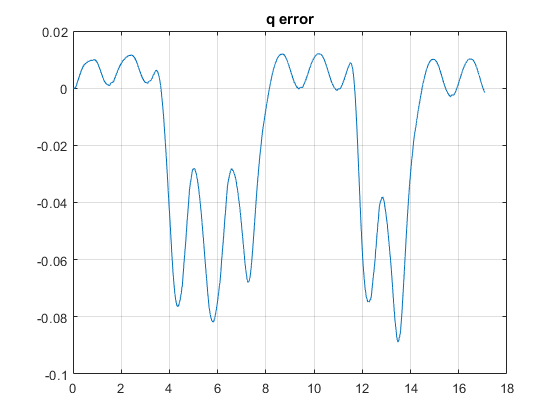


start = 1;
% finish = 500;
finish = data_length;

figure
plot(time, (ticks'-real(q_arr)))
% plot(time, q_arr)
grid on
title("q error")
xlim("auto")
ylim("auto")

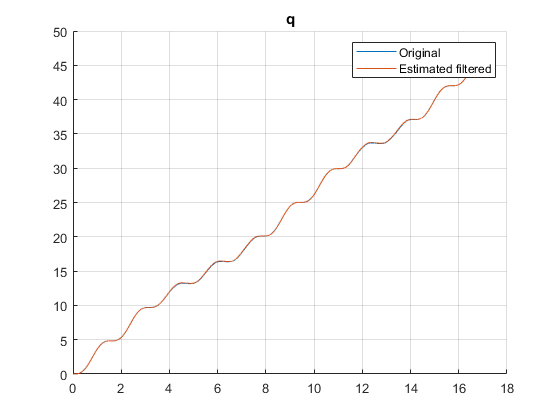


% figure
% plot(time, dticks'-real(x_arr(1, :)))
% % plot(time, q_arr)
% grid on
% title("dq error")
% xlim("auto")
% ylim("auto")

figure
hold on
plot(time(start:finish), ticks(start:finish))
plot(time(start:finish), q_arr(start:finish))
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

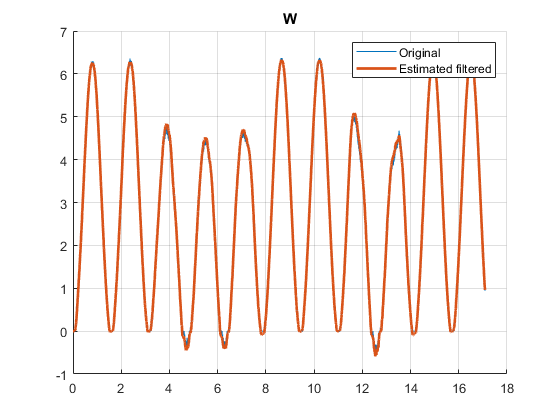


figure
hold on
plot(time(start:finish), dticks_orig(start:finish))
plot(time(start:finish), x_arr(1, start:finish), "LineWidth", 2)
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

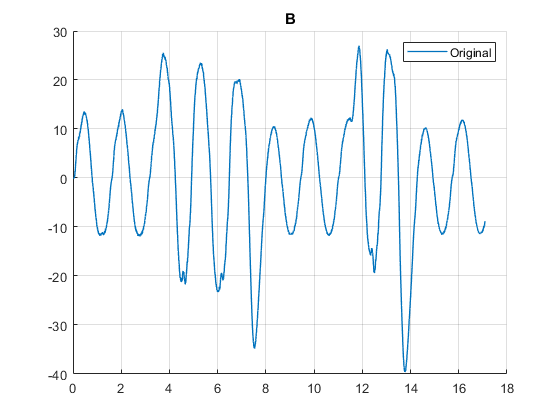


figure
hold on
% plot(time(start:finish), ddticks_orig(start:finish))
% plot(time(start:finish), ddticks(start:finish))
plot(time(start:finish), x_arr(2, (start:finish)), "LineWidth", 1)
hold off
grid on
title("B")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

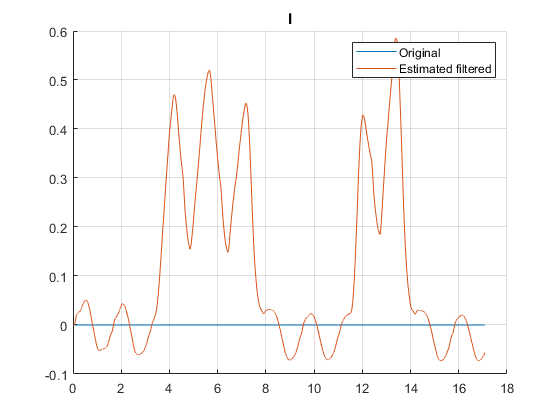


figure
hold on
plot(time(start:finish), current_orig(start:finish))
plot(time(start:finish), x_arr(3, (start:finish)))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

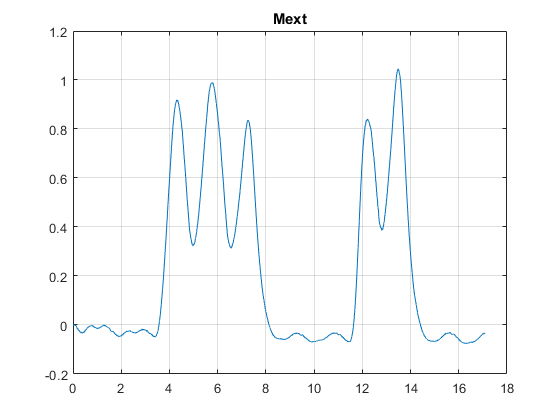


figure
plot(time, Mext_arr)
grid on
title("Mext")
xlim("auto")
ylim("auto")

### Parameters identification with kalman filter model with load

% from offline parameter identification with KF
L = 1.0551;
R = 5.9043;
Kw = 1.9437;
Km = 1.9437;
J = 0.0085;
Lam = 0.0020;

% V3 + load
% x = [w dw I]'
% u = [Mext u]'
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L]

A = 1.0e+03 *

   -0.0002         0    0.2287
   -0.4213   -0.0002   -1.2796
   -0.0018         0   -0.0056


B = [1/J 0;
     0   Km/(J*L);
     0   1/L]

B =   117.6471         0
         0  216.7288
         0    0.9478


C = eye(3)

C =      1     0     0
     0     1     0
     0     0     1


C_lqe = [1 0 0;
         0 1 0;
         0 0 0]

C_lqe =      1     0     0
     0     1     0
     0     0     0


D = [0 0 0]'

D =      0
     0
     0



[Te, De] = eig(A)

Te =    0.0000 + 0.0000i  -0.0069 - 0.0481i  -0.0069 + 0.0481i
   1.0000 + 0.0000i   0.9988 + 0.0000i   0.9988 + 0.0000i
   0.0000 + 0.0000i   0.0044 - 0.0000i   0.0044 + 0.0000i


De =   -0.2353 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.9156 +20.3488i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.9156 -20.3488i


Cc = ctrb(A,B)

Cc = 1.0e+05 *

    0.0012         0   -0.0003    0.0022   -0.4955   -0.0126
         0    0.0022   -0.4956   -0.0126    3.0066   -0.8421
         0    0.0000   -0.0022   -0.0001    0.0126   -0.0037


Cob = obsv(A, C_lqe)

Cob = 1.0e+04 *

    0.0001         0         0
         0    0.0001         0
         0         0         0
   -0.0000         0    0.0229
   -0.0421   -0.0000   -0.1280
         0         0         0
   -0.0421         0   -0.1333
    0.2556    0.0000   -8.8867
         0         0         0


rank(Cc)

ans = 3

rank(Cob)

ans = 3


Vd_w = 5e2;
Vd_dw = 1e2;
Vd_I = 1;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];

Vn = [2 0 0;
      0 1e5 0;
      0 0 1];

C_lqe = [1 0 0;
         0 1 0;
         0 0 0];

[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, 0.0015);
Kf

Kf =     0.9930   -0.0000         0
   -0.3130    0.0078         0
   -0.0014    0.0000         0



betta = 0.01 % коэффициент регуляризации

betta = 0.0100

k0 = 0.1 % начальное значение матрицы коэффициентов

k0 = 0.1000

% betta = 7 % коэффициент регуляризации
% k0 = 600 % начальное значение матрицы коэффициентов
I = eye(5) % диагональная единичная матрица

I =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


GAMMA_0 = k0.*I % матрица начальных значений коэффициентов

GAMMA_0 =     0.1000         0         0         0         0
         0    0.1000         0         0         0
         0         0    0.1000         0         0
         0         0         0    0.1000         0
         0         0         0         0    0.1000



Th_hat = [0; 0; 0; 0; 0]

Th_hat =      0
     0
     0
     0
     0


Th_hat(1) = L;
Th_hat(2) = R;
Th_hat(3) = Kw;
Th_hat(3) = Km;
Th_hat(4) = J;
Th_hat(5) = Lam;
Th_hat

Th_hat =     1.0551
    5.9043
    1.9437
    0.0085
    0.0020


Th_hat_start = Th_hat;
dTh_hat = [0; 0; 0; 0; 0]

dTh_hat =      0
     0
     0
     0
     0



G_hat = GAMMA_0

G_hat =     0.1000         0         0         0         0
         0    0.1000         0         0         0
         0         0    0.1000         0         0
         0         0         0    0.1000         0
         0         0         0         0    0.1000


dG_hat = zeros(5,5)

dG_hat =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



% dTh_hat = G_hat * fi * (u - fi' * Th_hat)
% dG_hat = -G_hat * fi * fi' * G_hat + betta * G_hat

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);
dI_arr = zeros(1, data_length);
Mext = 0;
Mext_arr = zeros(1, data_length);

[Te, De] = eig(A)

Te =    0.0000 + 0.0000i  -0.0069 - 0.0481i  -0.0069 + 0.0481i
   1.0000 + 0.0000i   0.9988 + 0.0000i   0.9988 + 0.0000i
   0.0000 + 0.0000i   0.0044 - 0.0000i   0.0044 + 0.0000i


De =   -0.2353 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.9156 +20.3488i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.9156 -20.3488i


At = expm(A*dt)

At =     0.9990         0    0.3940
   -0.7256    0.9996   -2.3487
   -0.0032         0    0.9897


Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B

Bt =    0.2037 - 0.0000i   0.0003 - 0.0000i
  -0.0741 + 0.0000i   0.3734 + 0.0000i
  -0.0003 - 0.0000i   0.0016 - 0.0000i


A_hat = (At-Kf*C_lqe)

A_hat =     0.0060    0.0000    0.3940
   -0.4127    0.9917   -2.3487
   -0.0018   -0.0000    0.9897


B_hat = [Bt Kf]

B_hat =    0.2037 - 0.0000i   0.0003 - 0.0000i   0.9930 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0741 + 0.0000i   0.3734 + 0.0000i  -0.3130 + 0.0000i   0.0078 + 0.0000i   0.0000 + 0.0000i
  -0.0003 - 0.0000i   0.0016 - 0.0000i  -0.0014 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i



count = 0;

for k = 2:data_length
    count = count + 1;
    t = time(k);
    dt = time(k) - time(k-1);
    u_act = input(k);
%     I_act = current(k);
%     dI_act = dI(k);
%     w_act = dticks(k);
%     dw_act = ddticks(k);
%     dw_act = ddticks_orig(k);

    u = [Mext input(k-1) (C_lqe*[dticks(k-1) ddticks(k-1) current(k-1)]')']';
    x_arr(:, k) = A_hat*x_arr(:, k-1)+B_hat*u;
    x_arr(:, k) = real(x_arr(:, k));
    q_arr(k) = q_arr(k-1) + x_arr(1, k-1)*dt;

    dI_act = (x_arr(3, k)-x_arr(3, k-1))/dt;
    dI_arr(k) = dI_act;
    w_act = x_arr(1, k);
    I_act = x_arr(3, k);
    dw_act = x_arr(2, k);

%     Mext = J*x_arr(2, k) + Lam*x_arr(1,k) - Km*x_arr(3,k);
    Mext = -J*x_arr(2, k) - Lam*x_arr(1,k) + Km*x_arr(3,k);
    Mext_arr(k) = real(Mext);

    phi = [dI_act 0;
           I_act  0;
           w_act -I_act;
           0 dw_act;
           0 w_act];
     phi_T = phi';

    %Gamma G_hat
    dG_hat = -G_hat * phi * phi_T * G_hat + betta * G_hat;
    G_hat = G_hat + dG_hat * dt;

    U = [u_act; Mext];

    Aa = -phi_T * Th_hat + U;
    dTh_hat =  G_hat * phi * Aa;
   
    Th_hat = Th_hat + dTh_hat * dt;

    L = Th_hat(1);
    R = Th_hat(2);
    Kw = Th_hat(3);
    Km = Th_hat(3);
    J = Th_hat(4);
    Lam = Th_hat(5);
    
    A = [-Lam/J        0      Km/J;
         -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
         -Kw/L         0     -R/L];
    B = [1/J 0;
         0   Km/(J*L);
         0   1/L];
end

Th_hat

Th_hat =     1.0860
    5.9245
    1.9490
    0.0063
    0.0357


eL = Th_hat(1)

eL = 1.0860

eR = Th_hat(2)

eR = 5.9245

eKw = Th_hat(3)

eKw = 1.9490

eKm = Th_hat(3)

eKm = 1.9490

eJ = Th_hat(4)

eJ = 0.0063

eLam = Th_hat(5)

eLam = 0.0357


Th_hat_start

Th_hat_start =     1.0551
    5.9043
    1.9437
    0.0085
    0.0020


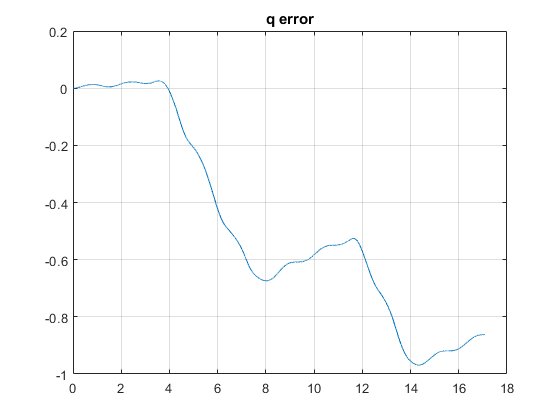


start = 1;
% finish = 500;
finish = data_length;

figure
plot(time, (ticks'-real(q_arr)))
% plot(time, q_arr)
grid on
title("q error")
xlim("auto")
ylim("auto")

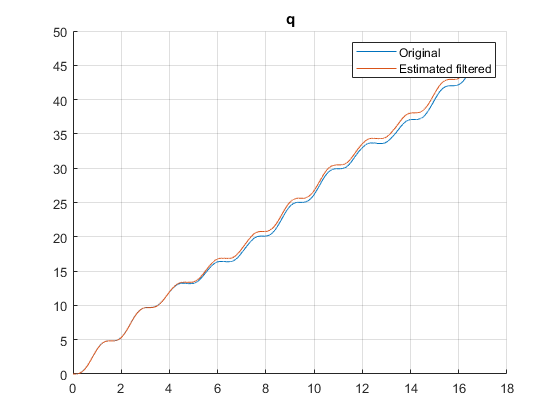


% figure
% plot(time, dticks'-real(x_arr(1, :)))
% % plot(time, q_arr)
% grid on
% title("dq error")
% xlim("auto")
% ylim("auto")

figure
hold on
plot(time(start:finish), ticks(start:finish))
plot(time(start:finish), q_arr(start:finish))
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

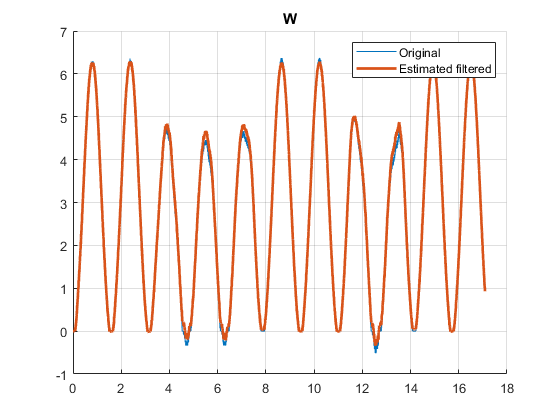


figure
hold on
plot(time(start:finish), dticks_orig(start:finish))
plot(time(start:finish), x_arr(1, start:finish), "LineWidth", 2)
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

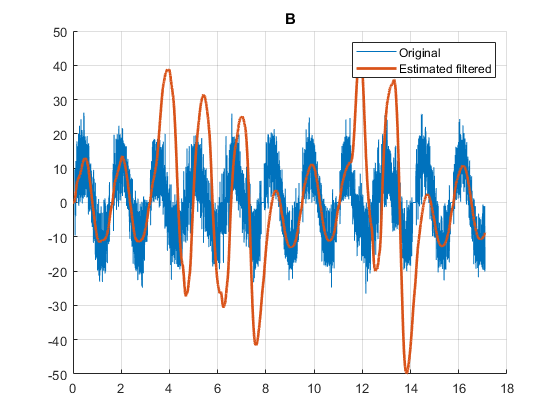


figure
hold on
% plot(time(start:finish), ddticks_orig(start:finish))
plot(time(start:finish), ddticks(start:finish))
plot(time(start:finish), x_arr(2, (start:finish)), "LineWidth", 2)
hold off
grid on
title("B")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

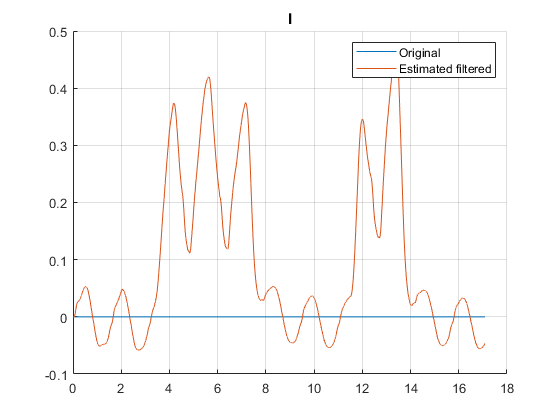


figure
hold on
plot(time(start:finish), current_orig(start:finish))
plot(time(start:finish), x_arr(3, (start:finish)))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

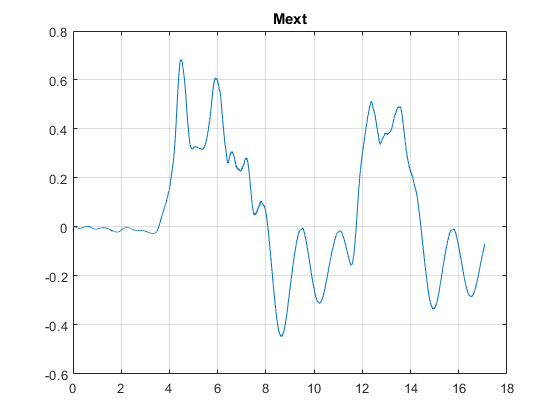


figure
plot(time, Mext_arr)
grid on
title("Mext")
xlim("auto")
ylim("auto")

### Parameters identification with kalman filter

% from offline parameter identification with KF
L = 1.0551;
R = 5.9043;
Kw = 1.9437;
Km = 1.9437;
J = 0.0085;
Lam = 0.0020;
Mext = 0;

% % V3
% % x = [w dw I]'
% % u = u
% A = [-Lam/J      0      Km/J;
%      -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
%      -Kw/L       0      -R/L]
% B = [0 Km/(J*L) 1/L]'
% C = eye(3)
% C_lqe = [1 0 0;
%          0 1 0;
%          0 0 0]
% D = [0 0 0]'

% V3 + load
% x = [w dw I]'
% u = [Mext u]'
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L]
B = [1/J 0;
     0   Km/(J*L);
     0   1/L]
C = eye(3)
C_lqe = [1 0 0;
         0 1 0;
         0 0 0]
D = [0 0 0]'

[Te, De] = eig(A)
Cc = ctrb(A,B)
Cob = obsv(A, C_lqe)
rank(Cc)
rank(Cob)

Vd_w = 100;
Vd_dw = 1e5;
Vd_I = 1;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];

Vn = [10 0 0;
      0 1e5 0;
      0 0 1];

C_lqe = [1 0 0;
         0 1 0;
         0 0 0];

[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, 0.009);
Kf

betta = 0.01 % коэффициент регуляризации
k0 = 0.1 % начальное значение матрицы коэффициентов
% betta = 7 % коэффициент регуляризации
% k0 = 600 % начальное значение матрицы коэффициентов
I = eye(6) % диагональная единичная матрица
GAMMA_0 = k0.*I % матрица начальных значений коэффициентов

Th_hat = [0; 0; 0; 0; 0; 0]
Th_hat(1) = L;
Th_hat(2) = R;
Th_hat(3) = Kw;
Th_hat(3) = Km;
Th_hat(4) = J;
Th_hat(5) = Lam;
Th_hat(6) = Mext;
Th_hat
dTh_hat = [0; 0; 0; 0; 0; 0]

G_hat = GAMMA_0
dG_hat = zeros(6,6)

% dTh_hat = G_hat * fi * (u - fi' * Th_hat)
% dG_hat = -G_hat * fi * fi' * G_hat + betta * G_hat

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);
dI_arr = zeros(1, data_length);
Mext_arr = zeros(1, data_length);

[Te, De] = eig(A)
At = expm(A*dt)
Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B
A_hat = (At-Kf*C_lqe)
B_hat = [Bt Kf]

count = 0;

for k = 2:data_length
% for k = 2:10
    count = count + 1;
    t = time(k);
    dt = time(k) - time(k-1);
    u_act = input(k);
%     I_act = current(k);
%     dI_act = dI(k);
%     w_act = dticks(k);
%     dw_act = ddticks(k);
%     dw_act = ddticks_orig(k);

    u = [Mext input(k-1) (C_lqe*[dticks(k-1) ddticks(k-1) current(k-1)]')']';
    x_arr(:, k) = A_hat*x_arr(:, k-1)+B_hat*u;
    x_arr(:, k) = real(x_arr(:, k));
    q_arr(k) = q_arr(k-1) + x_arr(1, k-1)*dt;

    dI_act = (x_arr(3, k)-x_arr(3, k-1))/dt;
    dI_arr(k) = dI_act;
    w_act = x_arr(1, k);
    I_act = x_arr(3, k);
    dw_act = x_arr(2, k);

    phi = [dI_act 0;
           I_act  0;
           w_act -I_act;
           0 dw_act;
           0 w_act;
           0 -1];
     phi_T = phi';

    %Gamma G_hat
    dG_hat = -G_hat * phi * phi_T * G_hat + betta * G_hat;
    G_hat = G_hat + dG_hat * dt;

    U = [u_act; 0];

    Aa = -phi_T * Th_hat + U;
    dTh_hat =  G_hat * phi * Aa;
   
    Th_hat = Th_hat + dTh_hat * dt;

    L = Th_hat(1);
    R = Th_hat(2);
    Kw = Th_hat(3);
    Km = Th_hat(3);
    J = Th_hat(4);
    Lam = Th_hat(5);
    Mext = Th_hat(6);

    Mext_arr(k) = Mext;
    
    A = [-Lam/J        0      Km/J;
         -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
         -Kw/L         0     -R/L];
%     B = [0 Km/(J*L) 1/L]';
    B = [1/J 0;
         0   Km/(J*L);
         0   1/L];
end

Th_hat
eL = Th_hat(1)
eR = Th_hat(2)
eKw = Th_hat(3)
eKm = Th_hat(3)
eJ = Th_hat(4)
eLam = Th_hat(5)
eMext = Th_hat(6)

start = 1;
% finish = 500;
finish = data_length;

figure
plot(time, (ticks'-real(q_arr)))
% plot(time, q_arr)
grid on
title("q error")
xlim("auto")
ylim("auto")

% figure
% plot(time, dticks'-real(x_arr(1, :)))
% % plot(time, q_arr)
% grid on
% title("dq error")
% xlim("auto")
% ylim("auto")

figure
hold on
plot(time(start:finish), ticks(start:finish))
plot(time(start:finish), q_arr(start:finish))
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

figure
hold on
plot(time(start:finish), dticks_orig(start:finish))
plot(time(start:finish), x_arr(1, start:finish), "LineWidth", 2)
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

figure
hold on
% plot(time(start:finish), ddticks_orig(start:finish))
plot(time(start:finish), ddticks(start:finish))
plot(time(start:finish), x_arr(2, (start:finish)), "LineWidth", 2)
hold off
grid on
title("B")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

figure
hold on
plot(time(start:finish), current_orig(start:finish))
plot(time(start:finish), x_arr(3, (start:finish)))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

figure
plot(time, Mext_arr)
grid on
title("Mext")
xlim("auto")
ylim("auto")

### Kalman filter state estimation parameters

% from offline parameter identification with KF
L = 1.0551;
R = 5.9043;
Kw = 1.9437;
Km = 1.9437;
J = 0.0085;
Lam = 0.0020;

% V3 + load
% x = [w dw I]'
% u = [Mext u]'
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L]
B = [1/J 0;
     0   Km/(J*L);
     0   1/L]
C = eye(3)
C_lqe = [1 0 0;
         0 1 0;
         0 0 0]
D = [0 0 0]'

[Te, De] = eig(A)
Cc = ctrb(A,B)
Cob = obsv(A, C_lqe)
rank(Cc)
rank(Cob)

Vd_w = 1;
Vd_dw = 1;
Vd_I = 1;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];

Vn = [1e2 0 0;
      0 1e3 0;
      0 0 1];

% [Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, 0.009); %115200 uart
[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, 0.0018); % 250000 uart
Kf

[Te, De] = eig(A);
Cc = ctrb(A,B)
Cob = obsv(A, C_lqe)
rank(Cc)
rank(Cob)

### KF estimation on raw data

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);
Mext = 0;
Mext_arr = zeros(1, data_length);

[Te, De] = eig(A)
At = expm(A*dt)
Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B
Bt = real(Bt)
A_hat = (At-Kf*C_lqe)
B_hat = [Bt Kf]

for k = 1:data_length-1
    u_act = input(k);
    u = [real(Mext) u_act (C_lqe*[dticks(k) ddticks(k) current(k)]')']';
    x_arr(:, k+1) = A_hat*x_arr(:, k)+B_hat*u;

    Mext = J*x_arr(2, k) + Lam*x_arr(1,k) - Km*x_arr(3,k);

    dt = time(k+1)-time(k);
    q_arr(k+1) = q_arr(k) + x_arr(1, k)*dt;
    Mext_arr(k) = real(Mext);
end

x_arr = real(x_arr);

% x_arr_d2 = x_arr;
% t_d2 = t;
% t = linspace(ts, tf, num_of_steps);
% q_err = ticks - q_m';

figure
plot(time, ticks'-real(q_arr))
% plot(time, q_arr)
grid on
title("q error")
xlim("auto")
ylim("auto")

% figure
% plot(time, dticks'-real(x_arr(1, :)))
% % plot(time, q_arr)
% grid on
% title("dq error")
% xlim("auto")
% ylim("auto")

figure
hold on
plot(time, ticks)
plot(time, real(q_arr))
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

figure
hold on
plot(time, dticks_orig)
plot(time, x_arr(1, :))
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

figure
hold on
% plot(time, ddticks_orig)
plot(time, ddticks)
plot(time, x_arr(2, :), "LineWidth", 2, "LineStyle", '--')
hold off
grid on
title("B")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

figure
hold on
plot(time, current_orig)
plot(time, x_arr(3, :))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

figure
plot(time, Mext_arr)
grid on
title("Mext")
xlim("auto")
ylim("auto")

Ah = [-eLam/eJ eKm/eJ; -eKw/eL -eR/eL]
Bh = [-1/eJ 0; 0 1/eL]
C = [1 0; 0 1]
D = [0 0; 0 0]

A = real(Ah)
B = real(Bh)

Amp = 6;
Bias = 6;
W = 4;
fi = 3.1415;

Const_input = [Amp Bias W fi, eMext];

t_f = time(data_length)
out2 = sim('model', t_f);

### Сравнение графиков мотора с оценочной моделью и фильтром калмана

o = out2.simout;

xx = linspace(0, time(data_length), data_length);
q_m = spline(o.q.Time, o.q.Data, xx);
q_err = ticks - q_m';

figure
title("Ошибка по углу")
plot(time, q_err)
xlabel("t, с")
ylabel("q, рад")

figure
title("Угол")
hold on
plot(time, ticks)
plot(o.q, '--')
plot(time, q_arr)
hold off
xlabel("t, с")
ylabel("q, рад")
legend("Original", "Model", "Integrated Kalman W")
legend("Position",[0.1381,0.78651,0.29286,0.12619])

figure
title("Угловая скорость")
hold on
plot(time, dticks)
plot(o.w, '--')
plot(time, x_arr(1, :))
hold off
xlabel("t, с")
ylabel("\omega, рад/с")
legend("Original", "Model", "Kalman")

figure
title("Угловое ускорение")
hold on
plot(time, ddticks)
% plot(time, ddticks_orig)
plot(o.dw, "LineWidth", 2)
plot(time, x_arr(2, :), "LineWidth", 2, "LineStyle", "--")
hold off
xlabel("t, с")
ylabel("\beta, рад/с")
legend("Original", "Model", "Kalman")

figure
title("Ток")
hold on
plot(time, current)
plot(o.I, "LineWidth", 2)
plot(time, x_arr(3, :), "LineWidth", 2, "LineStyle", "--")
hold off
xlabel("t, с")
ylabel("I, А")
legend("Original", "Model", "Kalman")

figure
title("Скорость изменения тока")
hold on
plot(time, dI)
plot(o.dI)
plot(time, dI_arr)
hold off
xlabel("t, с")
ylabel("dI, А/c")
legend("Original", "Model", "Kalman")
